# Task 3 - Number plate recognition

## Pre-processing

figure;

### Read images and turn them to grayscale

img_path = "images/final/task_3/";

image1 = imread(img_path + "dutch_example_2.png");
subplot(2, 2, 1); imshow(image1); title("Original Image");

img1gray = rgb2gray(image1);
subplot(2, 2, 2); imshow(img1gray); title("Grayscale");

### Noise removal

% Here I guess we could use imbilatfilt to filter it 
% bilaterally like in the documentation.
img1med = medfilt2(img1gray);
subplot(2, 2, 3); imshow(img1med); title("Noise Removal (Median Filter)");

### Contrast Enhancement 

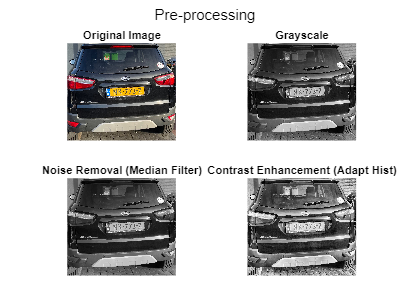

img1cont = adapthisteq(img1med);
subplot(2, 2, 4); imshow(img1cont); title("Contrast Enhancement (Adapt Hist)");

sgtitle("Pre-processing");

## Morphological Opening and Image Subtraction Operations

figure;

### Opening with 'disk'

se = strel('disk',35);
img1open = imopen(img1cont,se);
subplot(1, 3, 1); imshow(img1open); title("Disk Opening");

### Subtraction from enhanced image

img1sub = imsubtract(img1cont, img1open);
subplot(1, 3, 2); imshow(img1sub); title("Substract from Enhanced Image");

## Image binarization

% Find grayscale threshold and binarize
bins = 19;
[counts,x] = imhist(img1sub, bins);
g_thresh = otsuthresh(counts) %graythresh(img1sub)

g_thresh = 0.2778

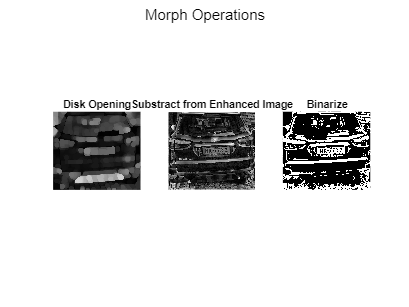


img1bin = imbinarize(img1sub, g_thresh);

%imshowpair(img1bin, img1bin_filled); 
subplot(1, 3, 3); imshow(img1bin);
title("Binarize");

sgtitle("Morph Operations");

## Creating Mask

figure;

### Detect edges with the Canny operator

th = [0 0.517]; %threshold for canny
s = sqrt(3); %sigma for canny

contour_mask = zeros(size(img1bin));
contour_mask(25:end-25,25:end-25) = 1;
img1contour =  activecontour(img1bin, contour_mask, 100);
img1edge = edge(img1contour, 'canny', th, s);

% Dilate to make sure lines are not interrupted
st = strel('rectangle', [9 9]);
img1edge_dil = imdilate(img1edge, st);

%imshow(img1edge); 
subplot(2, 3, 1); imshow(img1contour); title("Active Contour");
subplot(2, 3, 2); imshow(img1edge); title("Canny Edge Detection");
subplot(2, 3, 3); imshow(img1edge_dil); title("Dilate");

### Candidate plate area detection with Hough transform

Get top and bottom vertical lines of the plate (by minimum size of line)

% Transform
[H,T,R] = hough(img1edge_dil, 'RhoResolution', 1.5, 'Theta', -90:0.5:89);

% Retrieve nr of peaks
P = houghpeaks(H, 200, 'threshold', ceil(0.3*max(H(:))));

% use to find:
%   - minimum length we need = 500 for vertical lines
%   - min y_diff for left and right lines = ~80 +/-2
%   - max y_diff for left and right lines = ~105 +/-6
%   - min x_diff for top and bottom lines = ~473 +/-3
%   - max x_diff for top and bottom lines = ~480 +/-5
%imtool(img1edge_dil);

% Retrieve lines
fillgap_param = 3; % the minimum gap the line can have
minlen_param = 475; % the minimum length of the lines (high and get vertical lines)
lines = houghlines(img1edge_dil, T, R, P, 'FillGap', fillgap_param, 'MinLength', minlen_param);

subplot(2, 3, 4); imshow(img1edge_dil); title("Hough lines");
% Plot lines onto image
hold on
all_lines = {0, 0, 0}; % point1, point2, length
line_width = 3;
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    
    % Add line to list
    all_lines{k, 1} = lines(k).point1; % point1 - [x1,y1]
    all_lines{k, 2} = lines(k).point2; % point2 - [x2, y2]
    all_lines{k, 3} = abs(lines(k).point1 - lines(k).point2); % length point1 --> point2

    plot(xy(:,1),xy(:,2),'LineWidth', line_width, 'Color', 'green');
   
    % Plot beginnings and ends of lines
    plot(xy(1,1),xy(1,2),'x','LineWidth',line_width,'Color','yellow');
    plot(xy(2,1),xy(2,2),'x','LineWidth',line_width,'Color','red');
end

#### Find Plate Lines

Find the two lines most parallel to eachother to find the lines corresponding to the plate, by checking which 2 lines have the closest x- and y- coord to the other

% Get lines of interest from hough lines

% [xy1, xy2], [other_xy1, other_xy2], [x1_diff, x2_diff], [y1_diff, y2_diff]
lines_compare = {[0,0], [0,0], [0,0], [0,0]};

% to indicate from which line to start with to avoid duplicate
% comparisons
n = length(all_lines) - 1;
k = 0; % single incrementation for undefined final size of lines_compare
m = 1; % counter indicator for which other line to compare with
for i=1:length(all_lines)
    %disp("i: " + i + " | k: " + k + " | n: " + n);
    xy1 = all_lines{i, 1};
    xy2 = all_lines{i, 2};

    % Add all lines with eachother with the x difference between them
    for j=1:n
        k = k+1;
        other_xy1 = all_lines{j + m, 1};
        other_xy2 = all_lines{j + m, 2};

        lines_compare{k, 1} = [xy1, xy2]; % current line
        lines_compare{k, 2} = [other_xy1, other_xy2]; % other line
        lines_compare{k, 3} = [abs(xy1(1) - other_xy1(1)), abs(xy2(1) - other_xy2(1))]; % x diff
        lines_compare{k, 4} = [abs(xy1(2) - other_xy1(2)), abs(xy2(2) - other_xy2(2))]; % y diff
    end

    n = n - 1;
    m = m + 1;
end

min_y_diff = 105; % actual = 108
max_y_diff = 115; % actual = 111

min_x_diff = 5; % actual = 6
max_x_diff = 55; % actual = 50

filtered_lines = {[0,0], [0,0], [0,0], [0,0]};
filt_index = 0;
for i=1:40 %size(lines_compare, 1)
    filt_index = filt_index+1;

    max_y = max(lines_compare{i, 4});
    min_y = min(lines_compare{i, 4});
    max_x = max(lines_compare{i, 3});
    min_x = min(lines_compare{i, 3});

    % Check if x + y diff is within demanded range
    if (max_y_diff > max_y && min_y_diff < min_y && max_x_diff > max_x && min_x_diff < min_x)

        x1 =  lines_compare{i, 1}(1);
        y1 =  lines_compare{i, 1}(2);
        x2 =  lines_compare{i, 1}(3);
        y2 =  lines_compare{i, 1}(4);
        other_x1 =  lines_compare{i, 2}(1);
        other_y1 =  lines_compare{i, 2}(2);
        other_x2 =  lines_compare{i, 2}(3);
        other_y2 =  lines_compare{i, 2}(4);
        xs = [x1, x2, other_x2, other_x1];
        ys = [y1, y2, other_y2, other_y1];

        % Crop based on the corners
        topLeft = [min([x1, x2, other_x1, other_x2]), min([y1, y2, other_y1, other_y2])];
        topRight = [max([x1, x2, other_x1, other_x2]), min([y1, y2, other_y1, other_y2])];
        bottomLeft = [min([x1, x2, other_x1, other_x2]), max([y1, y2, other_y1, other_y2])];
        bottomRight = [max([x1, x2, other_x1, other_x2]), max([y1, y2, other_y1, other_y2])];

        %filtered_lines{filt_index, 1} = [xy1, xy2];
        %filtered_lines{filt_index, 2} = ;
        disp("Found lines in row: " + i);
        break
    end
end

Found lines in row: 40


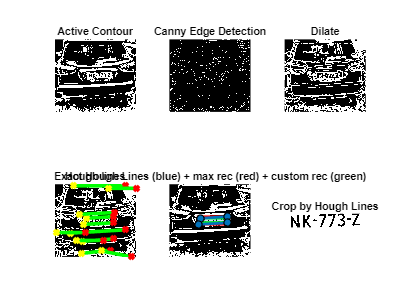


% rectangle pos = [x y w h] - x + y of lower left corner
rect_w_max = abs(bottomLeft(1) - bottomRight(1));
rect_h_max = abs(topLeft(2) - bottomLeft(2));
plate_bbox_rec_max = [topLeft(1), topLeft(2), rect_w_max, rect_h_max];


y_offset = 40; % make it smaller
x_offset = 40;
rect_w_min = abs(x1 - other_x2) - x_offset;
rect_h_min = abs(y2 - other_y2) - y_offset;
plate_bbox_rec_min = [x1 + 20, y1, rect_w_min, rect_h_min];

img_plate_crop = imcrop(img1bin, plate_bbox_rec_min);

subplot(2, 3, 5);  imshow(img1bin); title("Exact Hough Lines (blue) + max rec (red) + custom rec (green)");
hold on;
rectangle('Position', plate_bbox_rec_max, ...
            'LineWidth', 2, EdgeColor='r');
rectangle('Position', plate_bbox_rec_min, ...
            'LineWidth', 2, EdgeColor='g');
plate_bbox_poly = drawpolygon(gca, 'Position', [xs;ys]');
hold off;
subplot(2, 3, 6);  imshow(img_plate_crop); title("Crop by Hough Lines");

## OCR

figure;

Should make it only check for 

- Letters (Language) for the first 2 letters

- Numeric for the following 2 letters

- Letters for the middle 2 letters

- Numeric digits for the last 4 digits

img_ocr = img_plate_crop;

% remove dashes from plate by removing small objects
img1clean = ~bwareaopen(~img_ocr, 200);

plate_text = getLicensePlateByRegion_ocr(img1clean, PlateTypes.Dutch);

Found letters:


ans = 3

  1:  NK
Found digits:


ans = 3

  1:  511 


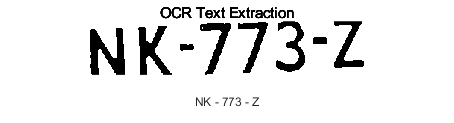

imshow(img_ocr); xlabel(plate_text);

sgtitle("OCR Text Extraction");

fclose('all');